import com.comsol.model.*
import com.comsol.model.util.*

ModelUtil.remove('Model');

model = ModelUtil.create('Model');

model.modelPath('C:\Users\cmadrigal\OneDrive - Estudiantes ITCR\COMSOL\Comsol\Modelo_test');

comp1 = model.component.create('comp1', true); % Creacion del componente 1

% Definicion de objeto 3D de geometria, parte del Componente 1
model.geom.create('geom1', 3);  
model.geom('geom1').model('comp1');

% Definicion de parametros
L =13.5;
rad1 = 8;
tbb = 7  ;
wbb = 8;
mh = 4;
htc = 4.5;
vTot = 20;

model.param.set('L', strcat(int2str(L),'[cm]'));
model.param.descr('L', 'Length');

model.param.set('rad_1', strcat(int2str(rad1),'[mm]'));
model.param.descr('rad_1', 'Bolt radius');

model.param.set('tbb', strcat(int2str(tbb),'[mm]'));
model.param.descr('tbb', 'Thickness');

model.param.set('wbb', strcat(int2str(wbb),'[cm]'));
model.param.descr('wbb', 'Width');

model.param.set('mh', strcat(int2str(mh),'[mm]'));
model.param.descr('mh', 'Maximum element size');

model.param.set('htc', strcat(int2str(htc), '[W/m^2/K]'));
model.param.descr('htc', 'Heat transfer coefficient');

model.param.set('Vtot', strcat(int2str(vTot),'[mV]'));
model.param.descr('Vtot', 'Applied electric potential');

## Definicion de geometria del busbar:

Extrusion de un dibujo en 2D a partir de un plano de trabajo

try
    % Crear plano de trabajo en xz, con todo objeto en el siendo tratado como 1
    model.geom('geom1').create('wp1', 'WorkPlane');
    model.geom('geom1').feature('wp1').set('unite', true);
    model.geom('geom1').feature('wp1').set('quickplane', 'xz');
    
    % Rectangulo 1, de dimensiones L+2*tbb X 0.1
    model.geom('geom1').feature('wp1').geom.create('r1', 'Rectangle');
    model.geom('geom1').feature('wp1').geom.feature('r1').set('size', {'L+2*tbb' '0.1'});
    
    % Rectangulo 2, de dimensiones L+tbb X 0.1-tbb, en la posicion [0, tbb]
    model.geom('geom1').feature('wp1').geom.create('r2', 'Rectangle');
    model.geom('geom1').feature('wp1').geom.feature('r2').set('size', {'L+tbb' '0.1-tbb'});
    model.geom('geom1').feature('wp1').geom.feature('r2').set('pos', {'0' 'tbb'});
    
    % Resta de los dos rectangulos para obtener una forma de "L"
    model.geom('geom1').feature('wp1').geom.create('dif1', 'Difference');
    model.geom('geom1').feature('wp1').geom.feature('dif1').selection('input').set({'r1'});
    model.geom('geom1').feature('wp1').geom.feature('dif1').selection('input2').set({'r2'});
    
    % Filete en esquina interna de la "L", de radio tbb, en el vertice #3
    model.geom('geom1').feature('wp1').geom.create('fil1', 'Fillet');  
    model.geom('geom1').feature('wp1').geom.feature('fil1').selection('point').set('dif1', 3);
    model.geom('geom1').feature('wp1').geom.feature('fil1').set('radius', 'tbb');
    
    % Filete en esquina externa de la "L", de radio 2*tbb, en el vertice #6
    model.geom('geom1').feature('wp1').geom.create('fil2', 'Fillet');
    model.geom('geom1').feature('wp1').geom.feature('fil2').selection('point').set('fil1', 6);
    model.geom('geom1').feature('wp1').geom.feature('fil2').set('radius', '2*tbb');
    
    % Se extruye la geometria final una distancia wbb, ubicada en el plano wp
    model.geom('geom1').feature.create('ext1', 'Extrude');
    model.geom('geom1').feature('ext1').setIndex('distance', 'wbb', 0);
    model.geom('geom1').feature('ext1').set('workplane', 'wp1');
    model.geom('geom1').feature('ext1').selection('input').set({'wp1'});
    mphgeom(model)

catch
    model.geom('geom1').feature('wp1').geom.run('r1');
    model.geom('geom1').feature('wp1').geom.run('r2');
    model.geom('geom1').feature('wp1').geom.run('dif1');
    model.geom('geom1').feature('wp1').geom.run('fil1');
    model.geom('geom1').feature('wp1').geom.run('fil2');
    model.geom('geom1').run('ext1');
end

## **Definicion de geometria de los tornillos:**

Extrucion de cilindros identicos que representan los tornillos

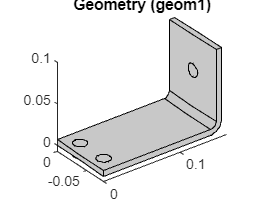

try
    % Plano de trabajo de primer cilindro, paralelo a la cara 8
    model.geom('geom1').create('wp2', 'WorkPlane');
    model.geom('geom1').feature('wp2').set('unite', true);
    model.geom('geom1').feature('wp2').set('planetype', 'faceparallel');
    model.geom('geom1').feature('wp2').selection('face').set('ext1', 8);
    
    % Circulo base, de radio rad_1
    model.geom('geom1').feature('wp2').geom.create('c1', 'Circle');
    model.geom('geom1').feature('wp2').geom.feature('c1').set('r', 'rad_1');
    model.geom('geom1').feature('wp2').geom.run('c1');
    
    % Cilindro extruido del circulo c1, desde el plano wp2 una distancia -2*tbb
    model.geom('geom1').feature.create('ext2', 'Extrude');
    model.geom('geom1').feature('ext2').set('workplane', 'wp2');
    model.geom('geom1').feature('ext2').selection('input').set({'wp2'});
    model.geom('geom1').feature('ext2').setIndex('distance', '-2*tbb', 0);
    
    % Nuevo plano de trabajo, paralelo a la cara 4 del busbar
    model.geom('geom1').create('wp3', 'WorkPlane');
    model.geom('geom1').feature('wp3').set('unite', true);
    model.geom('geom1').feature('wp3').set('planetype', 'faceparallel');
    model.geom('geom1').feature('wp3').selection('face').set('ext1', 4);
    
    % Circulo base a los tornillos en esa cara, de radio rad_1 y posicion [-L/2+1.5, -wbb/4]
    model.geom('geom1').feature('wp3').geom.create('c2', 'Circle');
    model.geom('geom1').feature('wp3').geom.feature('c2').set('r', 'rad_1');
    model.geom('geom1').feature('wp3').geom.feature('c2').set('pos', {'-L/2+1.5[cm]' '0'});
    model.geom('geom1').feature('wp3').geom.feature('c2').setIndex('pos', '-wbb/4', 1);
    
    % Copia de ese circulo base c2, a un c3 en otra posicion wbb/2
    model.geom('geom1').feature('wp3').geom.create('c3', 'Copy');
    model.geom('geom1').feature('wp3').geom.feature('c3').selection('input').set({'c2'});
    model.geom('geom1').feature('wp3').geom.feature('c3').set('disply', 'wbb/2');
    
    
    % Se extruyen los dos circulos para generar los dos tornillos una distancia -2*tbb
    model.geom('geom1').feature.create('ext3', 'Extrude');
    model.geom('geom1').feature('ext3').set('workplane', 'wp3');
    model.geom('geom1').feature('ext3').selection('input').set({'wp3'});
    model.geom('geom1').feature('ext3').setIndex('distance', '-2*tbb', 0);

catch
    model.geom('geom1').run('wp2');
    model.geom('geom1').run('ext2');
    model.geom('geom1').run('wp3');
    model.geom('geom1').run('ext3');
end

mphgeom(model)

%% Definicion de materiales
try
    % Material 1: Cobre, para el busbar. Se asigna a todo por defecto
    
    % Se define la instancia de material
    model.material.create('mat1');
    
    % Se declaran algunas propiedades del material
    model.material('mat1').label('Copper');
    model.material('mat1').set('family', 'copper');
    model.material('mat1').propertyGroup.create('Enu', 'Young''s modulus and Poisson''s ratio');
    model.material('mat1').propertyGroup.create('linzRes', 'Linearized resistivity');
    
    % Se le asignan valores a las propiedades del material
    model.material('mat1').propertyGroup('def').label('Basic');
    model.material('mat1').propertyGroup('def').set('relpermeability', {'1' '0' '0' '0' '1' '0' '0' '0' '1'});
    model.material('mat1').propertyGroup('def').set('electricconductivity', {'5.998e7[S/m]' '0' '0' '0' '5.998e7[S/m]' '0' '0' '0' '5.998e7[S/m]'});
    model.material('mat1').propertyGroup('def').set('thermalexpansioncoefficient', {'17e-6[1/K]' '0' '0' '0' '17e-6[1/K]' '0' '0' '0' '17e-6[1/K]'});
    model.material('mat1').propertyGroup('def').set('heatcapacity', '385[J/(kg*K)]');
    model.material('mat1').propertyGroup('def').set('density', '8960[kg/m^3]');
    model.material('mat1').propertyGroup('def').set('thermalconductivity', {'400[W/(m*K)]' '0' '0' '0' '400[W/(m*K)]' '0' '0' '0' '400[W/(m*K)]'});
    
    model.material('mat1').propertyGroup('Enu').label('Young''s modulus and Poisson''s ratio');
    model.material('mat1').propertyGroup('Enu').set('youngsmodulus', '110e9[Pa]');
    model.material('mat1').propertyGroup('Enu').set('poissonsratio', '0.35');
    
    model.material('mat1').propertyGroup('linzRes').label('Linearized resistivity');
    model.material('mat1').propertyGroup('linzRes').set('rho0', '1.72e-8[ohm*m]');
    model.material('mat1').propertyGroup('linzRes').set('alpha', '0.0039[1/K]');
    model.material('mat1').propertyGroup('linzRes').set('Tref', '298[K]');
    
    model.material('mat1').propertyGroup('linzRes').addInput('temperature');
    
    
    %% Material 2: Titanio, para los tornillos.
    
    % Se define la instancia de material
    model.material.create('mat2');
    
    % Se declaran algunas propiedades del material
    model.material('mat2').label('Titanium beta-21S');
    model.material('mat2').set('family', 'titanium');
    model.material('mat2').propertyGroup.create('Enu', 'Young''s modulus and Poisson''s ratio');
    
    % Se le asignan valores a las propiedades del material
    model.material('mat2').propertyGroup('def').label('Basic');
    model.material('mat2').propertyGroup('def').set('relpermeability', {'1' '0' '0' '0' '1' '0' '0' '0' '1'});
    model.material('mat2').propertyGroup('def').set('electricconductivity', {'7.407e5[S/m]' '0' '0' '0' '7.407e5[S/m]' '0' '0' '0' '7.407e5[S/m]'});
    model.material('mat2').propertyGroup('def').set('thermalexpansioncoefficient', {'7.06e-6[1/K]' '0' '0' '0' '7.06e-6[1/K]' '0' '0' '0' '7.06e-6[1/K]'});
    model.material('mat2').propertyGroup('def').set('heatcapacity', '710[J/(kg*K)]');
    model.material('mat2').propertyGroup('def').set('relpermittivity', {'1' '0' '0' '0' '1' '0' '0' '0' '1'});
    model.material('mat2').propertyGroup('def').set('density', '4940[kg/m^3]');
    model.material('mat2').propertyGroup('def').set('thermalconductivity', {'7.5[W/(m*K)]' '0' '0' '0' '7.5[W/(m*K)]' '0' '0' '0' '7.5[W/(m*K)]'});
    
    model.material('mat2').propertyGroup('Enu').label('Young''s modulus and Poisson''s ratio');
    model.material('mat2').propertyGroup('Enu').set('youngsmodulus', '105e9[Pa]');
    model.material('mat2').propertyGroup('Enu').set('poissonsratio', '0.33');
    
    %% Seleccion
    % Se le asigna a los todos los elementos del el material 1 (cobre)
    model.material('mat1').selection.all;
    
    % Se le asigna a los elementos de los tornillos el material 2 (titanio)
    % Estos valores sobreescriben el cobre
    model.material('mat2').selection.set([2 3 4 5 6 7]);
    
    % Con esta configuracion, mas adelante 
    % se notaran los materiales en el resultado
    model.view('view1').set('scenelight', true);
    model.view('view1').set('showmaterial', true);

catch
    model.material('mat1').run;
    model.material('mat2').run;
end

Error using run (line 33)
'scriptname' must be a text scalar.

%% Definicion de fisicas (Objetivo: Calentamiento de Joule)

try
    % Definicion de fisica de transferencia de calor
    % Todos los bordes que no son busbar/tornillo transfieren calor
    model.physics.create('ht', 'HeatTransfer', 'geom1');
    model.physics('ht').model('comp1');
    
    model.physics('ht').create('hf1', 'HeatFluxBoundary', 2);  % 2 => Fronteras
    model.physics('ht').feature('hf1').set('HeatFluxType', 'InwardHeatFlux');
    
    model.physics('ht').feature('hf1').selection.set([1:7 9:14 16:42]);
    model.physics('ht').feature('hf1').set('h', 'htc');  % Y definir el hcf
    
    
    % Definicion de fisica de medios conductivos
    % El borde del tornillo solitario es la fuente, la tierra los otros dos
    model.physics.create('ec', 'ConductiveMedia', 'geom1');
    model.physics('ec').model('comp1');
    
    model.physics('ec').create('pot1', 'ElectricPotential', 2);
    model.physics('ec').feature('pot1').selection.set([43]);
    model.physics('ec').feature('pot1').set('V0', 'Vtot');
    
    model.physics('ec').create('gnd1', 'Ground', 2);
    model.physics('ec').feature('gnd1').selection.set([8 15]);
    
    
    % Definicion de multifisica de calentamiento electromagnetico
    % Aplica para todo el modelo
    model.multiphysics.create('emh1', 'ElectromagneticHeating', 'geom1', 3);  % 3 => Vertices
    model.multiphysics('emh1').set('EMHeat_physics', 'ec');
    model.multiphysics('emh1').set('Heat_physics', 'ht');
    model.multiphysics('emh1').selection.all;

catch
    model.physics('ec').run;
    model.physics('ht').run;
    model.multiphysics('emh1').run;
end

%% Mallado
try
    % Definicion de la malla
    model.mesh.create('mesh1', 'geom1');
    
    % Definicion de propiedades de la malla,
    % El mallado en este caso se hace con tetrahedros
    model.mesh('mesh1').feature.create('ftet', 'FreeTet');
    % Tambien el rango de tamanos y el factor de curvatura
    model.mesh('mesh1').automatic(false);
    model.mesh('mesh1').feature('size').set('custom', true);
    model.mesh('mesh1').feature('size').set('hmax', 'mh');
    model.mesh('mesh1').feature('size').set('hmin', 'mh-mh/3');
    model.mesh('mesh1').feature('size').set('hcurve', 0.2);
    model.mesh('mesh1').run;

catch
    model.mesh('mesh1').run;
end

mphmesh(model)

%% Estudio y solucion

try
    % Definicion del estudio
    model.study.create('std1');
    model.study('std1').create('stat', 'Stationary');
    model.study('std1').feature('stat').activate('ec', true);
    model.study('std1').feature('stat').activate('ht', true);
    model.study('std1').feature('stat').activate('emh1', true);
    
    % Definicion de la solucion
    model.sol.create('sol1');
    model.sol('sol1').study('std1');
catch
end

model.sol('sol1').runAll

## Graficas (exportadas directamente de Comsol)

Grafica de potencial electrico

try
    model.result.create('pg1', 'PlotGroup3D');
    model.result('pg1').label(['Potencial el' native2unicode(hex2dec({'00' 'e9'}), 'unicode') 'ctrico (ec)']);
    model.result('pg1').set('frametype', 'spatial');
    model.result('pg1').set('data', 'dset1');
    model.result('pg1').feature.create('mslc1', 'Multislice');
    model.result('pg1').feature('mslc1').set('colortable', 'RainbowLight');
    model.result('pg1').feature('mslc1').set('data', 'parent');
catch
end

model.result('pg1').run;
mphplot(model, 'pg1')

Grafica de temperatura superficial

try    
    model.result.create('pg2', 'PlotGroup3D');
    model.result('pg2').label('Temperatura (ht)');
    model.result('pg2').set('data', 'dset1');
    model.result('pg2').feature.create('surf1', 'Surface');
    model.result('pg2').feature('surf1').label('Superficie');
    model.result('pg2').feature('surf1').set('expr', 'T');
    model.result('pg2').feature('surf1').set('colortable', 'ThermalLight');
    model.result('pg2').feature('surf1').set('data', 'parent');
    % Se definenrangos de valores para que se note el diferencial de color
    model.result('pg2').feature('surf1').set('rangecolormax', 330.960645576687);
    model.result('pg2').feature('surf1').set('rangecolormin', 322.923094901252);
catch
end

model.result('pg2').run;
mphplot(model, 'pg2')

Grafica de contornos isotermicos

try
    model.result.create('pg3', 'PlotGroup3D');
    model.result('pg3').label(['Contornos isot' native2unicode(hex2dec({'00' 'e9'}), 'unicode') 'rmicos (ht)']);
    model.result('pg3').set('data', 'dset1');
    model.result('pg3').feature.create('iso1', 'Isosurface');
    model.result('pg3').feature('iso1').label('Isosuperficie');
    model.result('pg3').feature('iso1').set('expr', 'T');
    model.result('pg3').feature('iso1').set('number', 10);
    model.result('pg3').feature('iso1').set('levelrounding', false);
    model.result('pg3').feature('iso1').set('colortable', 'ThermalLight');
    model.result('pg3').feature('iso1').set('data', 'parent');
catch
end

model.result('pg3').run;
mphplot(model, 'pg3', 'server', 'on')